## APPM 4560 Homework 1 - 1/23/26 - Will Pfaltzgraff

## Problem 1

# (a)

P1 = 3*exp(-2)

P1 = 0.4060

# (b)

P2 = nchoosek(100,0)*(0.02^0)*(0.98^100)+nchoosek(100,1)*0.02*(0.98^99)

P2 = 0.4033

P3 = P1 - P2

P3 = 0.0027

# (c)

P4 = (4*exp(-2))/(factorial(2))

P4 = 0.2707

P5 = P1 + P4

P5 = 0.6767

P_final = P4/P5

P_final = 0.4000

## Problem 2

# (b)

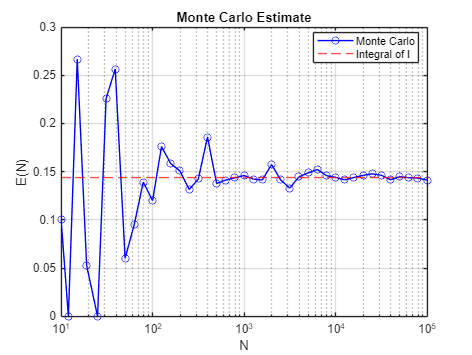

fu =@(u) (u.^4)./(u.^6+1); % Substitued function on u[0,1]

u = 1:0.1:5; % x with from 0 to 5 with step size from problem
n = floor(10.^u); % N = floor(10^x)
E = zeros(size(n)); % E(N) definition

for i = 1:length(n)
    N = n(i); % Populate N
    U = rand(N, 1); % Generate U
    V = rand(N, 1); % Generate another V
    E(i) = mean(V <= fu(U)); % True if above the curve false if below
end

I = integral(@(x) 1./(1+x.^6), 1, Inf);

figure;
semilogx(n, E, 'o-', 'Color', 'b'); 
hold on;
yline(I, '--', 'color', 'r');
xlabel('N');
ylabel('E(N)');
legend('Monte Carlo', 'Integral of I')
legend('Location','best');
title('Monte Carlo Estimate');
grid on;

## Problem 4

# (b)

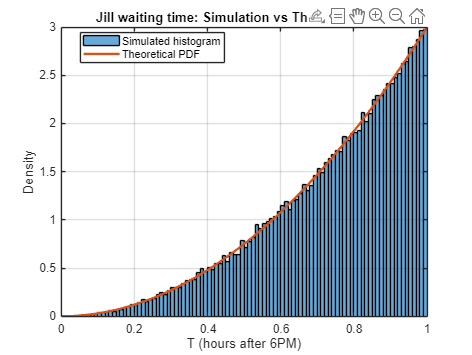

N = 10^5; % N of size in problem

A = rand(N, 1); % Agnes arrival time simulation
M = rand(N, 1); % Moe ""
D = rand(N, 1); % Dorothy ""

T = max([A M D], [], 2); % time all have arrived

t = linspace(0, 1, 1000);
tpdf = 3*(t.^2);

figure;
histogram(T, 'Normalization','PDF');  % from the homework doc
hold on;
plot(t, tpdf, 'LineWidth', 2);
xlabel('T (hours after 6PM)');
ylabel('Density');
title('Jill waiting time: Simulation vs Theoretical PDF');
legend('Simulated histogram','Theoretical PDF','Location','best');
xlim([0 1]);
grid on;